clear
close all
clc


% サンプルデータをload 
fileName = 'DemoDataSJ' ;
load(fileName) ;


% *** 実験実習で測定計測したデータ を load***
fileName = 'Data_S08' ; % ←　被験者番号を指定する
load(fileName) ;

Data = DataStruct.CMJ(1) ; % ←　条件名・試行番号を指定する
grfs = Data.Forces ;
Markers = Data.Markers ;
% ****



# **スティックピクチャ**

スティックピクチャを作成すると、どのような動作なのか分かりやすい

※　各フレームの xyz 座標データを plot, plot3 関数に与えてお絵描きをするだけなのだが、そこそこ面倒なので、進矢の作成した stickPicture 関数を使ってください

※　stickPicture は、マーカー座標データが、構造体として格納されていることが前提

※　プログラミングに慣れてきたら、使いやすいように自作してください

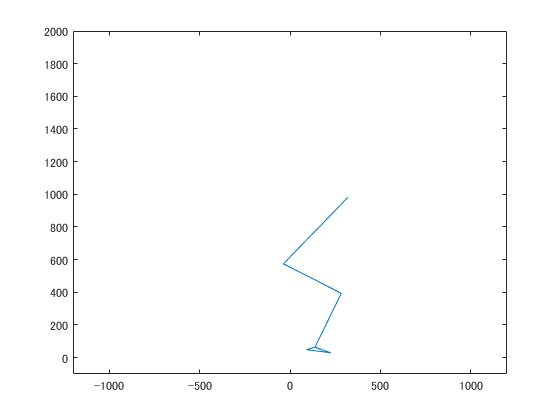


% プロットするマーカー名をセル配列で指定する
MarkerNames = {'Shoulder', 'Gt', 'Knee', 'Ankle', 'MP5', 'Heel', 'Ankle'} ;

% プロットしたいフレーム番号を指定する　（時系列が縦に並んでいることを想定しているので、行番号）
iFrame = 1 ;

% stickPicture 関数（自作）をコール
stickPicture(Markers, MarkerNames, iFrame, 'yz') ; % 4つめの引数 'yz' で、矢状面プロットを指定している
set(gca, 'xlim', [-1200,1200], 'ylim', [-100, 2000])

# **応用例: 時系列が分かるように、複数のスティックピクチャを重ね書き**

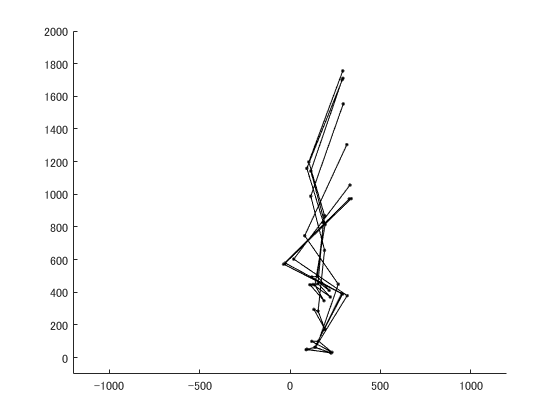

figure; hold on
for iFrame = [1800:100:2500] % 繰り返し実行のプログラミング：　for loop
    stickPicture(Markers, MarkerNames, iFrame, 'yz', 'k.-') ; 
end
set(gca, 'xlim', [-1200,1200], 'ylim', [-100, 2000])

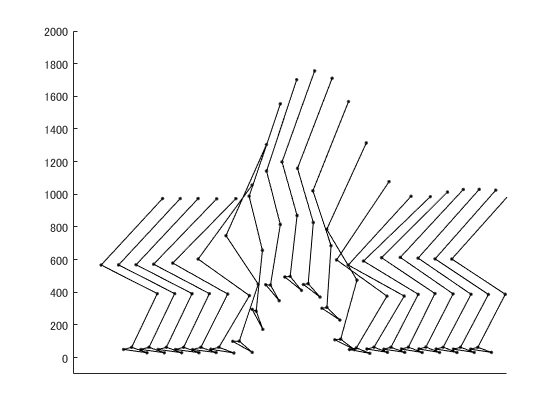


figure; hold on
MarkerFieldNames = fieldnames(Markers) ;
Markers2 = Markers ;
for iFrame = [1500:100:3500] % 繰り返し実行のプログラミング：　for loop
    for iMarker = 1:length(MarkerFieldNames)
        Markers2.(MarkerFieldNames{iMarker})(:,2) = Markers.(MarkerFieldNames{iMarker})(:,2) - 1800 + iFrame ;
    end
    stickPicture(Markers2, MarkerNames, iFrame, 'yz', 'k.-') ; 
end
set(gca, 'xlim', [-500,2000], 'ylim', [-100, 2000])
set(gca, 'xtick', [])

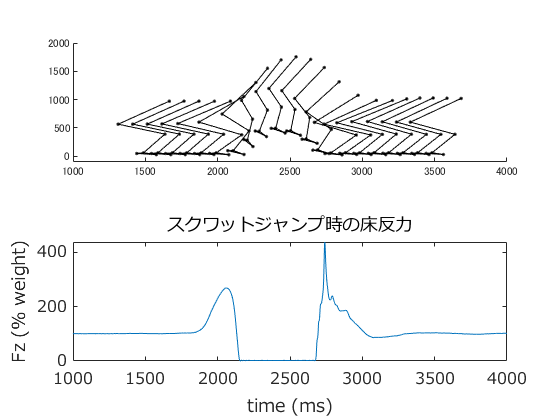

% 床反力データ
fzL = grfs(:,3) ; % 3列目は、左足が受けた床反力
fzR = grfs(:,6) ; % 6列目は、右足が受けた床反力
fz = fzL + fzR ;  % 左右の床反力を足して、身体が地面から受けた床反力
fzPercentWeight = fz * 100 ; % 100倍した方がグラフ的に見やすい説　（分かりやすい変数名にしておくこと）


figure;
subplot(2,1,1) ; hold on
MarkerFieldNames = fieldnames(Markers) ;
Markers2 = Markers ;
for iFrame = [1500:100:3500] % 繰り返し実行のプログラミング：　for loop
    for iMarker = 1:length(MarkerFieldNames)
        Markers2.(MarkerFieldNames{iMarker})(:,2) = Markers.(MarkerFieldNames{iMarker})(:,2) - 150 + iFrame ;
    end
    stickPicture(Markers2, MarkerNames, iFrame, 'yz', 'k.-') ; 
end
set(gca, 'xlim', [1000,4000], 'ylim', [-100, 2000])
% set(gca, 'xtick', [])

subplot(2,1,2) ;
plot(fzPercentWeight)
ylabel('Fz (% weight)')
xlabel('time (ms)')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')
set(gca, 'xlim', [1000, 4000])
title('スクワットジャンプ時の床反力')